# ENEL 561, Lab 01: Pre-Lab (Differential Equations)

The following is the derivation for the governing differential equations. From the lab manual, the following equations are already defined:  


$$\tau_m =k_t {\cdot i}_m \left(t\right),\;\;\;\tau_m \left(t\right)=J_{\mathrm{eq}} \frac{d\omega_m \left(t\right)}{\mathrm{dt}}$$


We can make the substitution for m and then isolate for $i_m \left(t\right)$:


$$i_m \left(t\right)=\frac{\tau_m }{k_t }=\frac{J_{\mathrm{eq}} }{k_t }\cdot \frac{d\omega_m \left(t\right)}{\mathrm{dt}}$$


 The lab manual also shows the equation from Kirchhoff’s Voltage Law and then isolate for $i_m \left(t\right)$:


$$v_m \left(t\right)-R_m i_m \left(t\right)-k_m \omega_m \left(t\right)=0$$



$$i_m \left(t\right)=\frac{v_m \left(t\right)-k_m \omega_m \left(t\right)}{R_m }$$


We can then make the substitution for $i_m \left(t\right)$ and isolate for $\frac{d\omega_m \left(t\right)}{\mathrm{dt}}$:


$$\frac{J_{\mathrm{eq}} }{k_t }\cdot \frac{d\omega_m \left(t\right)}{\mathrm{dt}}=\frac{v_m \left(t\right)-k_m \omega_m \left(t\right)}{R_m }$$



$$\frac{d\omega_m \left(t\right)}{\mathrm{dt}}=\frac{k_t }{R_m \cdot J_{\mathrm{eq}} }\left\lbrack v_m \left(t\right)-k_m \omega_m \left(t\right)\right\rbrack$$


We can also use the following equation for the angular position ($\theta_m$): 


$$\frac{d\theta_m \left(t\right)}{\mathrm{dt}}=\omega_m \left(t\right)$$
 

This makes the final set of differential equations:


$$\frac{d\omega_m \left(t\right)}{\mathrm{dt}}=\frac{k_t }{R_m \cdot J_{\mathrm{eq}} }\left\lbrack v_m \left(t\right)-k_m \omega_m \left(t\right)\right\rbrack$$



$$\frac{d\theta_m \left(t\right)}{\mathrm{dt}}=\omega_m \left(t\right)$$


Many of the parameters are defined in the lab manual including:

$R_m =8\ldotp 4\Omega ,\;k_t =0\ldotp 042\;N\cdot m$/$A,\;\;k_m =0\ldotp 042\;V$/$\left(\frac{\mathrm{rad}}{s}\right),$


$$J_m =\left(4\ldotp 0\right)\cdot {10}^{-6} \;\mathrm{kg}\cdot m^2 ,{\;\;\;J}_h =\left(0\ldotp 6\right)\cdot {10}^{-6} \;\mathrm{kg}\cdot m^2 ,\;m_d =0\ldotp 053\;\mathrm{kg},\;r_d =0\ldotp 0248\;m$$


We can determine Jeq using the following equation:


$$J_{\mathrm{eq}} =J_m +J_h +J_d ,\;\;J_d =\frac{1}{2}m_d {\left(r_d \right)}^2$$



$$J_{\mathrm{eq}} =\left(4\ldotp 0\right)\cdot {10}^{-6} +$$

$$\left(0\ldotp 6\right)\cdot {10}^{-6} \;\mathrm{kg}+\frac{1}{2}\left(0\ldotp 053\right){\left(0\ldotp 0248\right)}^2$$



$$J_{\mathrm{eq}} =2\ldotp 089856\cdot {10}^{-5} \;\mathrm{kg}\cdot m^2$$


Now the angle and speed of the disk can be determined, using the final equations defined. The angle and speed will be calculated for by using Euler's method to approximate the values.

In this section, all the required variables are being initialized for solving the differential equations using Euler's Method.

% Initializing variables
h=0.002;              % Step count (seconds)
a=0;                  % Starting time (seconds)
b=10;                 % Ending time (seconds)
m=(b-a)/h;            % Number of elements for voltage, speed, and angle arrays
W=zeros(1,m+1);       % Initializing angular speed array
W(1)=0;               % Setting first element of angular speed to 0 rad/s (initial condition)
theta=zeros(1, m+1);  % Initializing rotational angle position array
theta(1)=0;           % Setting first element of rotational angle position to 0 rad (initial condition)
starting = m/10;      % Helper variable to skip over the first second when writing voltage values
t=a:h:b;              % Time array with step size of h (0.002) over the 10 second interval

Here, all the constants defined above are initialized into the program.

% Initializing constants used for calculations
k_t = 0.042;                                    % Torque Constant 
k_m = 0.042;                                    % Motor Back-emf Constant 
R_m = 8.4;                                      % Terminal Resistance 
J_eq = 4.6 * 10^-6 + (0.5 * 0.053 * 0.0248^2);  % Equivalent Inertia of hub, disk, and rotor

Now we create a voltage signal that is at 0V from 0 - 1 seconds, then goes up to 5V from 1 second to 10 seconds. The starting variable is to skip the first second and write 5V to the remaining 9 seconds. 

V = zeros(1, m+1);
V(starting:m+1)=5;

Using Euler's Method to solve the differential equations for both rotational angle position, and the angular speed. 

%Euler's method to solving differential equations
for i=1:m    
    W(i+1) = W(i) + h * (k_t / (R_m * J_eq)) * (V(i) - k_m * W(i));
    theta(i+1) = theta(i) + h * W(i);
end

Plotting the voltage, angular speed, and rotational angle position against time on separate plots:

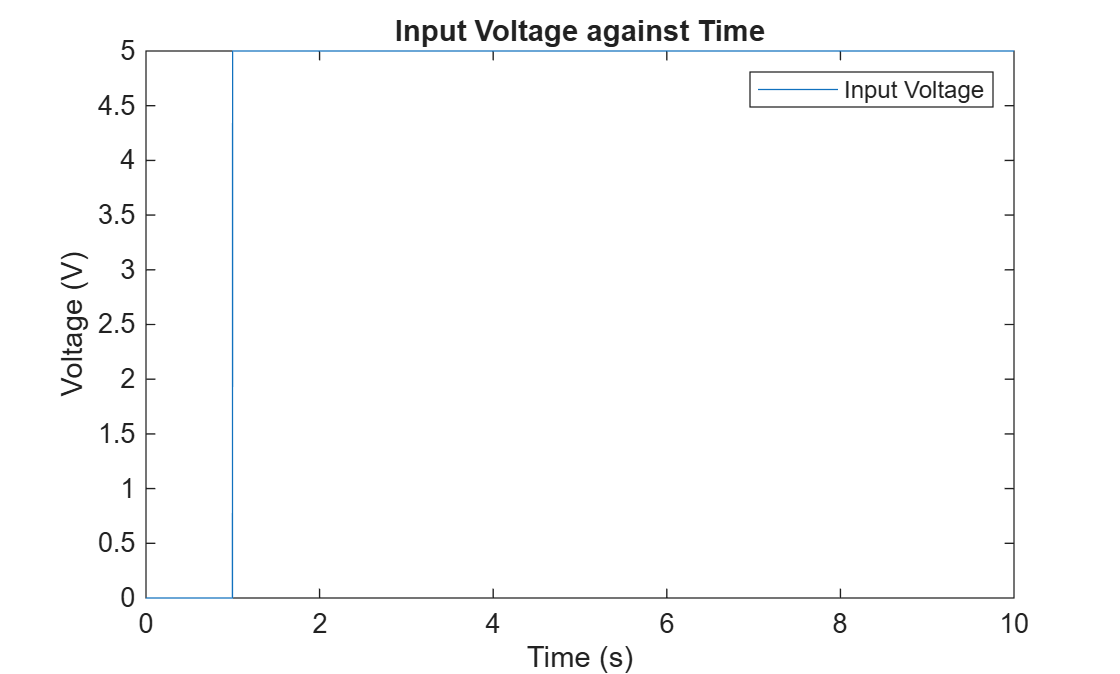

plot(t, V), xlabel('Time (s)'), ylabel('Voltage (V)')
legend("Input Voltage")
title("Input Voltage against Time")
hold off

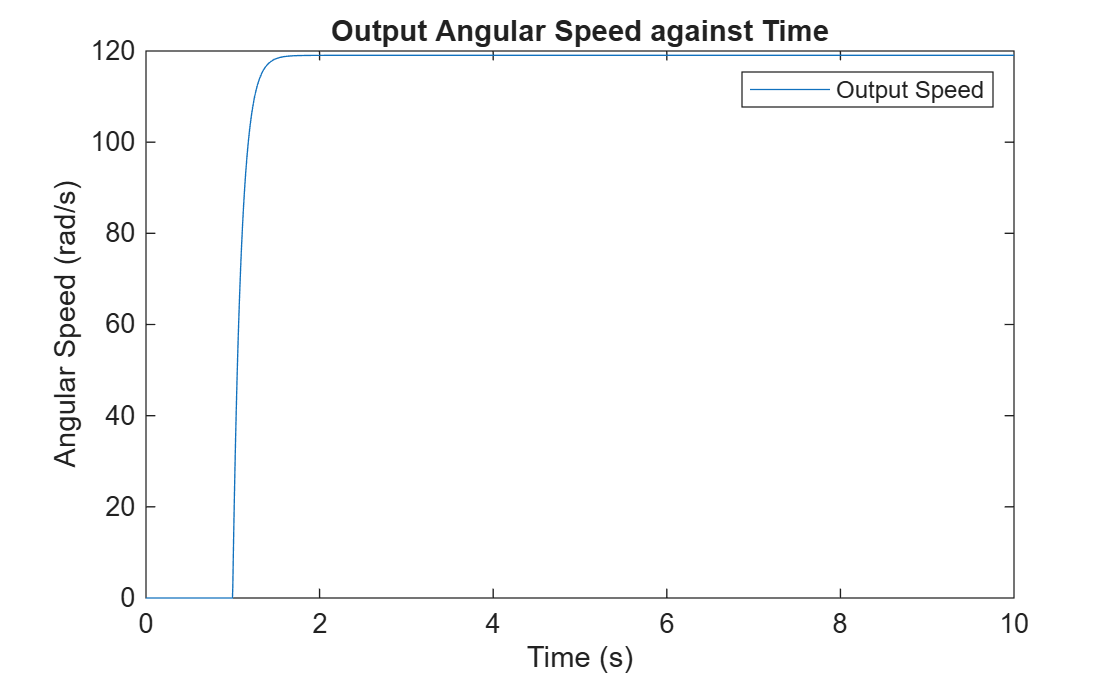

plot(t, W), xlabel('Time (s)'), ylabel('Angular Speed (rad/s)')
legend("Output Speed")
title("Output Angular Speed against Time")
hold off

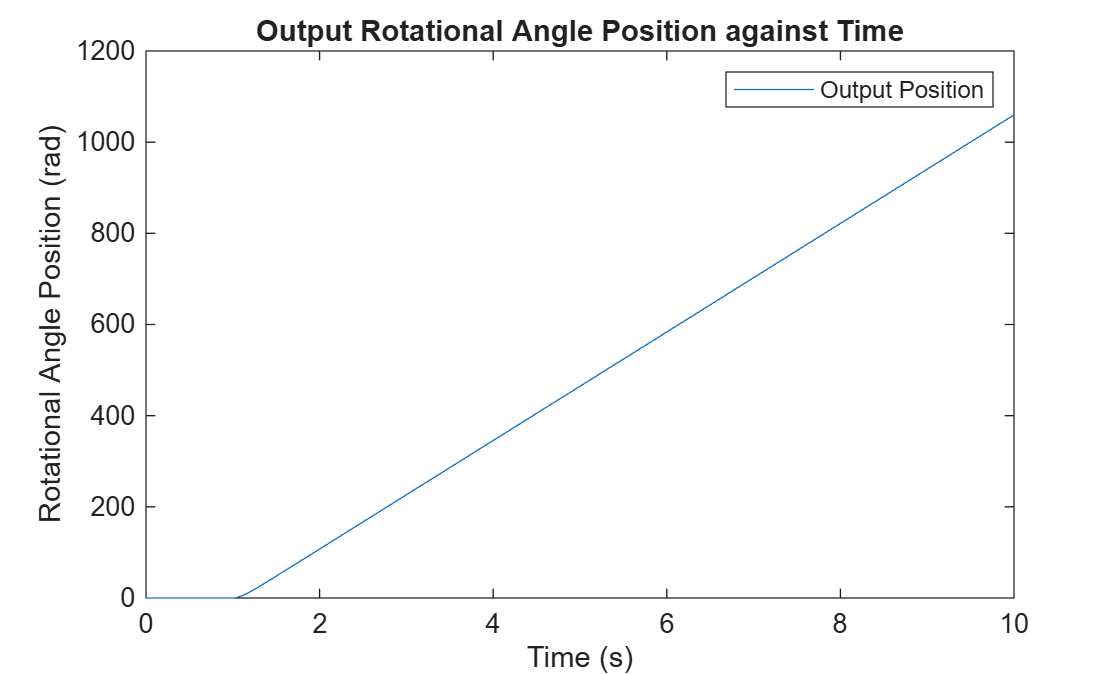

plot(t, theta), xlabel('Time (s)'), ylabel('Rotational Angle Position (rad)')
legend("Output Position")
title("Output Rotational Angle Position against Time")
hold off